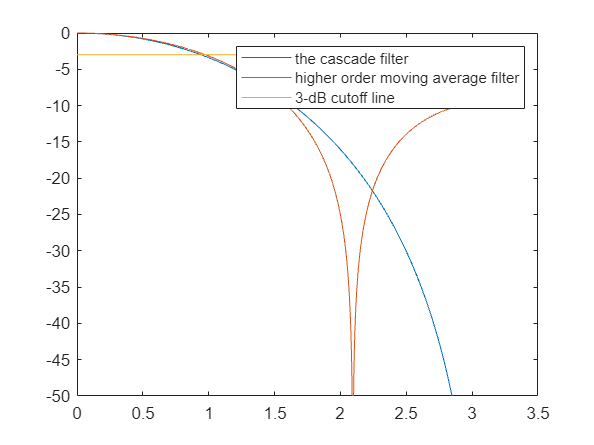

clc;close all;clear;
M=3;
w=linspace(0,pi,5000);

figure
H_ejw=(exp(-1i*3*w/2).*cos(w/2)).^3;
plot(w,20*log10(abs(H_ejw)));

hold on;
H_average=(1/M)*sin(M.*w/2).*exp(-1i*2.*w)./sin(w/2);
plot(w,20*log10(abs(H_average)));
ylim([-4,-2])
plot(w,-3*ones(1,5000));
ylim([-50,0]);
legend('the cascade filter','higher order moving average filter','3-dB cutoff line');